# Supplimentary Figure 1: Minimum energy scatter


%% Initialize
clear all;
omniHDF5File = 'C:\Users\nithin\Documents\GitHub\LargeFiles\omni\omni.h5';
[maginput,timeMaginput]=generate_maginput(omniHDF5File,'26 Mar 2008 09:00','26 Mar 2008 12:00');

timeArr = datenum('26-Mar-2008 11:19');
lat = 65.1:0.005:65.25;
timeStr = datestr(timeArr);
t = datetime(timeStr,'InputFormat','dd-MMM-yyyy HH:mm:ss');

GEOPACK_RECALC(year(t),day(t,'dayofyear'),hour(t),minute(t),second(t));
global GEOPACK1;
C = define_universal_constants;

thisTime = datenum(timeStr);
thisMaginput = interp1(timeMaginput',maginput,thisTime);
kp = round(thisMaginput(1)/10)+1;
PARMOD = zeros(10,1);
PARMOD(1) = kp;
PARMODT96 = zeros(10,1);
PARMODT96(1) = thisMaginput(5);
PARMODT96(2) = thisMaginput(2);
PARMODT96(3) = thisMaginput(6);
PARMODT96(4) = thisMaginput(7);

nLat = length(lat);
alt = 110;
lon = -147.47;

for i = 1:1:nLat

    thisLat = lat(i);
    xGEO = onera_desp_lib_rotate([alt, thisLat, lon],'gdz2geo');
    xGSM = onera_desp_lib_rotate(xGEO,'geo2gsm',thisTime);

    [~,~,~,XX{i},YY{i},ZZ{i},~] = GEOPACK_TRACE (xGSM(1),xGSM(2),xGSM(3),...
        1.0,50,(6371.2+110)/6371.2,0,PARMODT96,'T96','GEOPACK_IGRF_GSM');
    
    Kc{i} = geopack_find_curvature(XX{i},YY{i},ZZ{i});
    
    
    [maxKc,indx] = max(Kc{i});
    minRc = 1./maxKc;
    magEq{i} = [XX{i}(indx),YY{i}(indx),ZZ{i}(indx)];
    XRE(i) = XX{i}(indx);
    [BX,BY,BZ] = T96(0,PARMODT96,GEOPACK1.PSI,magEq{i}(1),magEq{i}(2),magEq{i}(3));
    KE(i) = ((((minRc.*C.RE ).*(C.e).*(BZ*10^-9)).^2).*(2^-7).*(C.me).^-1).*(10^-3).*(C.e).^-1; %keV

end

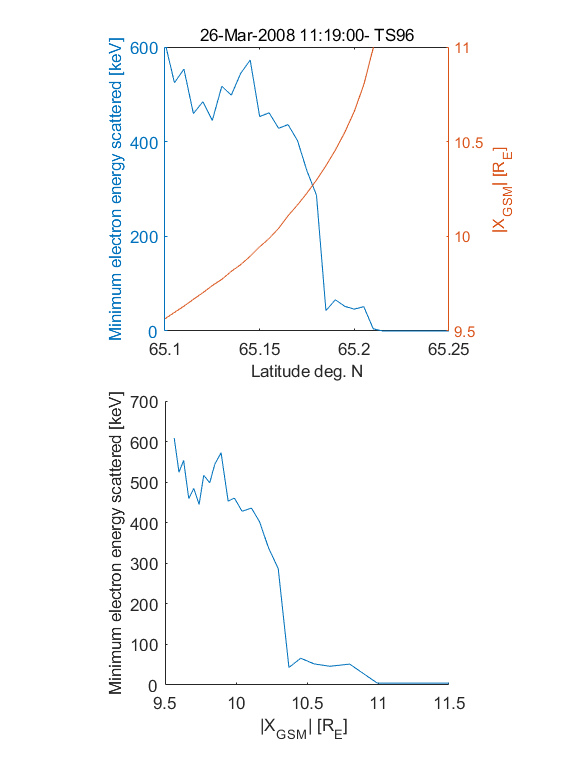


h=figure;
p=create_panels(h,'totalPanelNo',2,'demargin',15,'panelHeight',60,'panelBreadth',60);

p(1,1).select();
title([timeStr, '- TS96']);
ax=plotyy(lat,KE,lat,abs(XRE));
xlabel('Latitude deg. N');
ylabel(ax(1),'Minimum electron energy scattered [keV]')
ylabel(ax(2),'|X_G_S_M| [R_E]');
% xlim([65.1 65.25]);
% ylim([0 600]);
set(ax(1),'yLim',[0 600]);
set(ax(2),'yLim',[9.5 11],'YTick',[9.5,10,10.5,11]);
p(1,2).select();
plot(abs(XRE),KE);
xlabel('|X_G_S_M| [R_E] ')
ylabel('Minimum electron energy scattered [keV]');
xlim([9.5,11.5]);